# **Automated Unit Tests**

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;

%suite = TestSuite.fromClass(?mypackage.MyTestClass);
runner = TestRunner.withTextOutput;
suite = TestSuite.fromFolder("Testing/TestSuite");
result = runner.run(suite);

Running rightTriTest
....
Done rightTriTest
__________



# **Manual Unit Tests**

Discrete Time Consensus

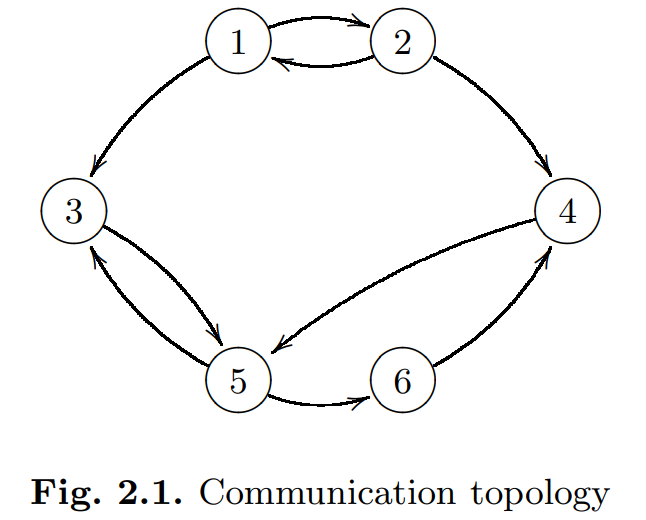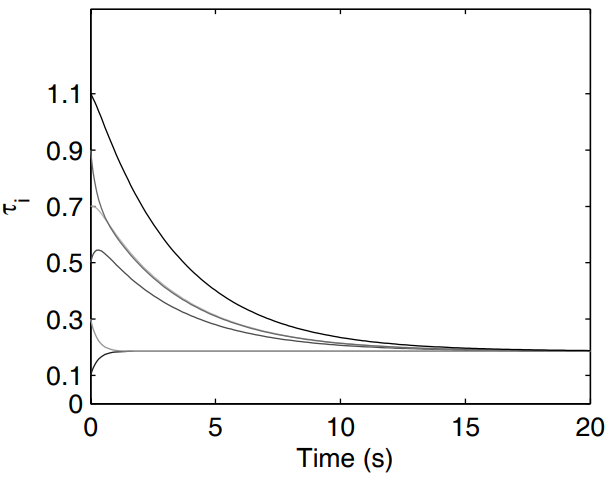

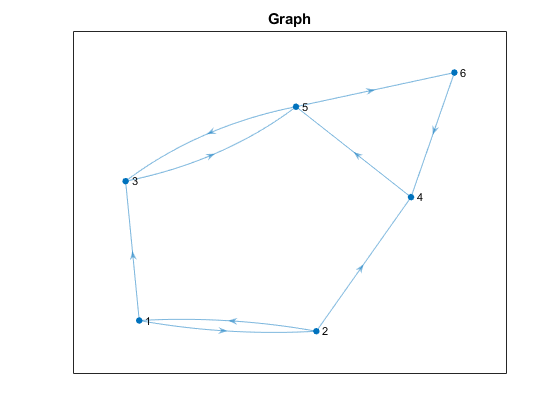

import ConsensusMAS.*;

% TOY
SIZE = 6;
A = [0 1.5 0 0 0 0; 2 0 0 0 0 0; 0.9 0 0 0 1.9 0; 0 1.2 0 0 0 1.3; 0 0 1.4 1.8 0 0; 0 0 0 0 0.7 0];
X0 = 0.2*(1:SIZE) - 0.1;

% Create the finite time network
network = NetworkFT(A, X0);
network.Simulate('timestep', 0.5, 'mintime', 20);
network.PlotGraph;

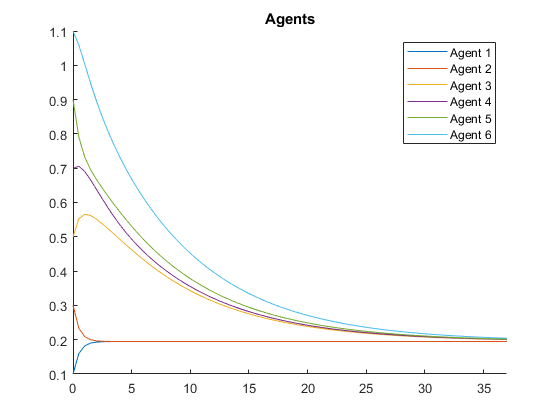

network.PlotStates;